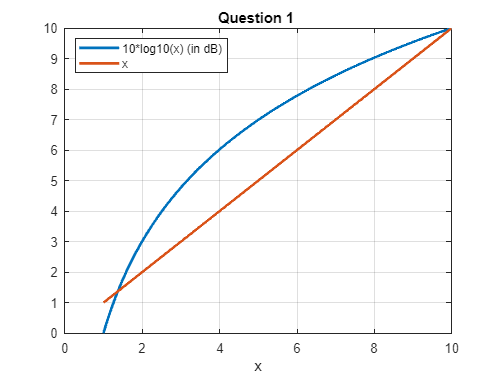

%Question 1

x = 1:0.01:10;
y = 10 * log10(x);
plot(x, y,'LineWidth',2);
hold on;
plot(x, x,'LineWidth',2);
legend({'10*log10(x) (in dB)', 'x'}, 'Location', 'NorthWest');
xlabel('x');
grid on;
title('Question 1 ');

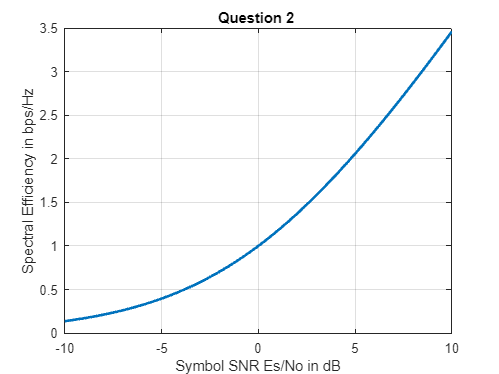

%Question 2

figure;
x=-10:0.1:10;
z = 10.^(x/10);
y = log2(1+z);
plot(x,y,'LineWidth',2);
xlabel('Symbol SNR Es/No in dB');
ylabel('Spectral Efficiency in bps/Hz');
grid on;
title('Question 2 ');

%{
(a)The mismatch we see is that when lambda -> 0 the value for eta_b on the graph is 1 but in our analysis, we got the value for eta_b as 0.
The reason for this mismatch is the graph we plotted is in linear scale whereas the values of lambda are in decibel scale. 
One way to remove this mismatch is to plot the graph against a logarithmic scale.
%}

%For reference of the above the code goes like:-
%x=-10:0.1:10;
%z = 10.^(x/10);
%y = log2(1+z);
%plot(z,y,'LineWidth',2);
%xlabel('Symbol SNR Es/No in dB');
%ylabel('Spectral Efficiency in bps/Hz');
%grid on;
%title('Question 2 z y ');





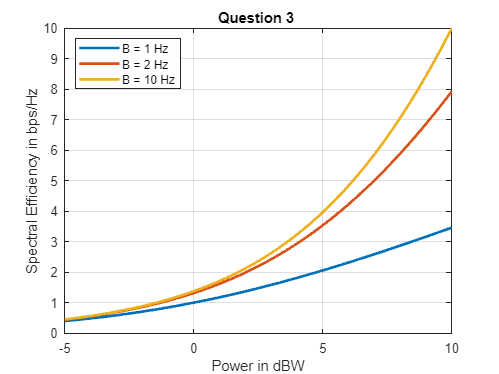

%Question 3

figure;
Ps = -5:0.1:10; 
B=1;
Pslinear=10.^(Ps/10);
C=B*log2(1+Pslinear./B);
plot(Ps,C,'LineWidth',2);
hold on;
B=5;
Pslinear=10.^(Ps/10);
C=B*log2(1+Pslinear./B);
plot(Ps,C,'LineWidth',2);
hold on;
B=10;
Pslinear=10.^(Ps/10);
C=B*log2(1+Pslinear./B);
plot(Ps,C,'LineWidth',2);
legend({'B = 1 Hz','B = 2 Hz', 'B = 10 Hz'}, 'Location', 'NorthWest');
xlabel('Power in dBW');
ylabel('Spectral Efficiency in bps/Hz');
grid on;
title('Question 3 ');


%{
The graph between eta_b and power looks similar to the graph between eta_b because both the graphs are plotting the same equation with a different scale. 
Since both the variations of eta_b are derived from the same equation : Shannon's Channel Capacity Equation.
%}


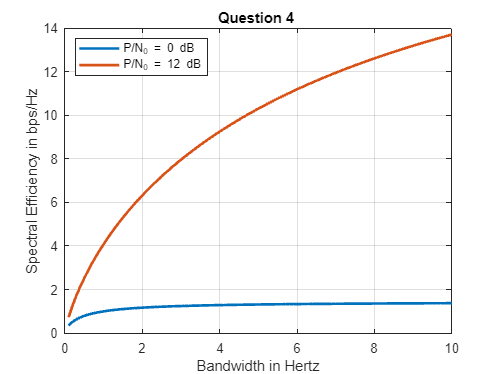

%Question 4

figure;
B = 0:0.1:10; 
Ps = 0;
Ps = 10.^(Ps./10);
C = B.*(log2(1+(Ps)./B));
plot(B,C,'LineWidth',2);
hold on;
Ps = 12;
Ps = 10.^(Ps./10);
C = B.*(log2(1+(Ps)./B));
plot(B,C,'LineWidth',2);
legend({'P/N_0 = 0 dB','P/N_0 = 12 dB'}, 'Location', 'NorthWest');
xlabel('Bandwidth in Hertz');
ylabel('Spectral Efficiency in bps/Hz');
grid on;
title('Question 4 ');


%{
The graph shows us how channel capacity varies with B for some fixed received power level. This fixed value of data rate/ channel capacity is different with different values of B 
In the case of P/N_0 = 0dB, the limiting value is around 1.44 which is in agreement with our analytical answer in 4(b) which is 1/ln(2) = 1/(0.69) = 1.44
%}


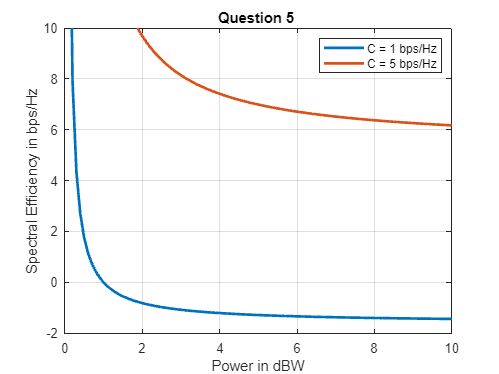

%Question 5

figure;
B=0:0.1:10;
C=1;
Ps = ((2.^(C./B))-1).*B;
Ps = 10*log10(Ps);
ylim([-2 10]);
plot(B,Ps,'LineWidth',2);
C=5;
hold on;
Ps = ((2.^(C./B))-1).*B;
Ps = 10*log10(Ps);
ylim([-2 10]);
plot(B,Ps,'LineWidth',2);
legend({'C = 1 bps/Hz','C = 5 bps/Hz'});
xlabel('Power in dBW');
ylabel('Spectral Efficiency in bps/Hz');
grid on;
title('Question 5 ');

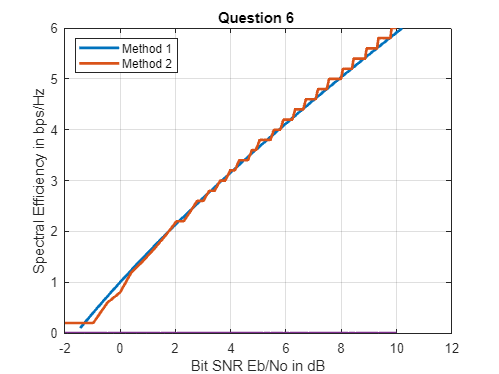

%Question 6
%Method 1

figure;
nb=0:0.1:6;

ratio=((2.^nb)-1)./(nb);
ratio = 10.*log10(ratio);
plot(ratio,nb,'LineWidth',2);
hold on;
xaxis = 0:0.1:10;

yaxis = 0:0.2:6;
val = zeros(length(xaxis));
tolerance=0.1;
for i = 1:length(xaxis)
    left = 1;
    right = length(yaxis);
    
    while left <= right
        mid = floor((left + right) / 2);
        x = yaxis(mid);
        alpha = (2^x - 1) / x;
        
        if alpha >= xaxis(i)
            val(i) = x;
            right = mid - 1;
        else
            if (xaxis(i)-alpha)<=tolerance
               val(i)=x;
               break;
            end
            left = mid + 1;
        end
    end
end

plot(10.*log10(xaxis), val,'LineWidth',2);
xlim([-2,12]);
legend({'Method 1','Method 2'}, 'Location', 'NorthWest');
xlabel('Bit SNR Eb/No in dB');
ylabel('Spectral Efficiency in bps/Hz');
grid on;
title('Question 6 ');


%{
The value of E_b/N_0 when eta_B becomes zero is -1.59 in dB which is equal to the analytical answer ln(2) in linear scale.

We get the analytical answer by finding lim eta_b->0 (2^eta_b -1)/eta_b and getting value for E_b/N_0
(L'Hospital Rule)
%}